# **EEG ANALYSIS**

# EEG Preprocessing

## 0. Load Data 

*eeg_raw*: contains data of 12 eeg channels + 1 ecg channel

subject = input('Subject: '); 

channelName = {'O1', 'O2', 'Fp1', 'Fp2', 'P7', 'P8', ...
               'P3', 'P4', 'F3', 'F4', 'T7', 'T8'};

file = sprintf("C:/Users/Natchira/Documents/M.Eng/Class - Semester 2/EGBE601 Medical Signal Processing/Final_Project/dataset/crop/variable_Subject%d.mat", subject);

% Generate variable names for y1 to y13
varsToLoad = {'data_path', 'filename', 'fs', 'numChannel', 'numSamples'};
for i = 1:12
    varsToLoad{end+1} = sprintf('y%d_csv', i);
end

% Load the specified variables
dataStruct = load(file, varsToLoad{:});
fs = dataStruct.fs;

% Assuming raw_eeg data is stored in y1 to y13 variables in the .mat file
eeg_raw = zeros(dataStruct.numSamples, length(channelName)); % Preallocate based on your data structure

for i = 1:12
    channelData = dataStruct.(sprintf('y%d_csv', i));
    eeg_raw(:, i) = channelData;
end

## 0. Crop Data (70 minutes)

Pre-driving (5 minutes) + Driving (60 minutes) + Post-driving (5 minutes)

*raw_eeg_crop*: 70-minute data of 12 eeg channels + 1 ecg channels

% crop data
start_second = [61 61 34 88 37 52 41.5 51 35.5 16.5 160 35.5 53 29 20];
end_second = start_second + 4200; % 70 minutes in seconds
start_index = round(start_second(subject) * dataStruct.fs) + 1;
end_index = round(end_second(subject) * dataStruct.fs);

eeg_raw_crop = eeg_raw(start_index:end_index, :);

datalength = size(eeg_raw_crop, 1);

numSamples = fs*60*70;

save(sprintf("C:/Users/Natchira/Documents/M.Eng/Class - Semester 2/EGBE601 Medical Signal Processing/Final_Project/dataset/eeg_Subject%d.mat", subject), 'eeg_raw_crop')

## 1. Load Data 

*eeg_raw*: contains data of 12 eeg channels

subject = input('Subject: '); 

channelName = {'O1', 'O2', 'Fp1', 'Fp2', 'P7', 'P8', ...
               'P3', 'P4', 'F3', 'F4', 'T7', 'T8'};

file = sprintf("C:/Users/Natchira/Documents/M.Eng/Class - Semester 2/EGBE601 Medical Signal Processing/Final_Project/dataset/eeg_Subject%d.mat", subject);

% load .mat file with the arrray 'ecg_data' inside
eeg_raw = load(sprintf("C:/Users/Natchira/Documents/M.Eng/Class - Semester 2/EGBE601 Medical Signal Processing/Final_Project/dataset/eeg_Subject%d.mat", subject));
eeg_raw = eeg_raw.eeg_raw_crop;

## 3. Filter

**Lowpass Filter: *****eeg_lowpass***

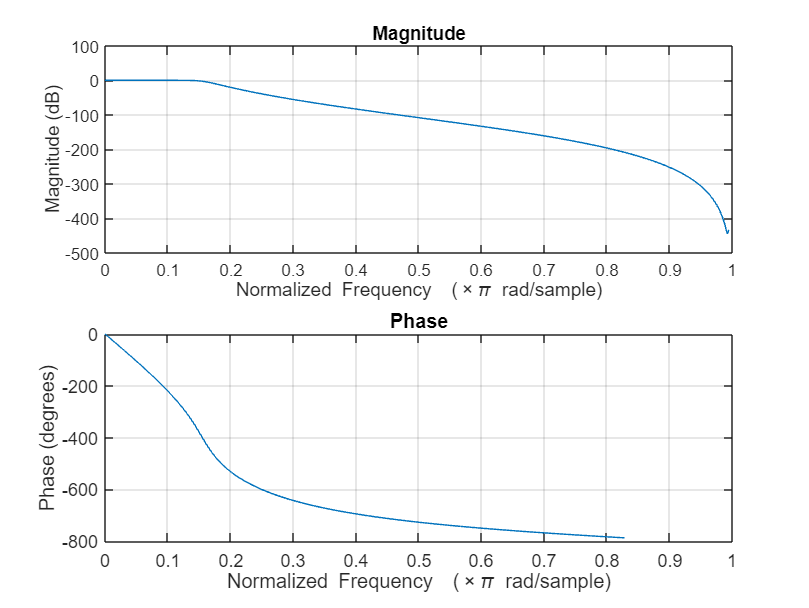

%% Low Pass Filter 
% Order
lowpass_order = 9;

% Cutoff frequencies (Hz)
lowpass_freq = 40;

% Calculate normalized cutoff frequencies
lowpass_Wn = lowpass_freq / (fs/2);

% Design lowpass Butterworth filter
[x, y] = butter(lowpass_order, lowpass_Wn, 'Low');

freqz(x, y)


eeg_lowpass = filtfilt(x, y, eeg_raw_crop);

**Highpass Filter: *****eeg_lowhighpass***

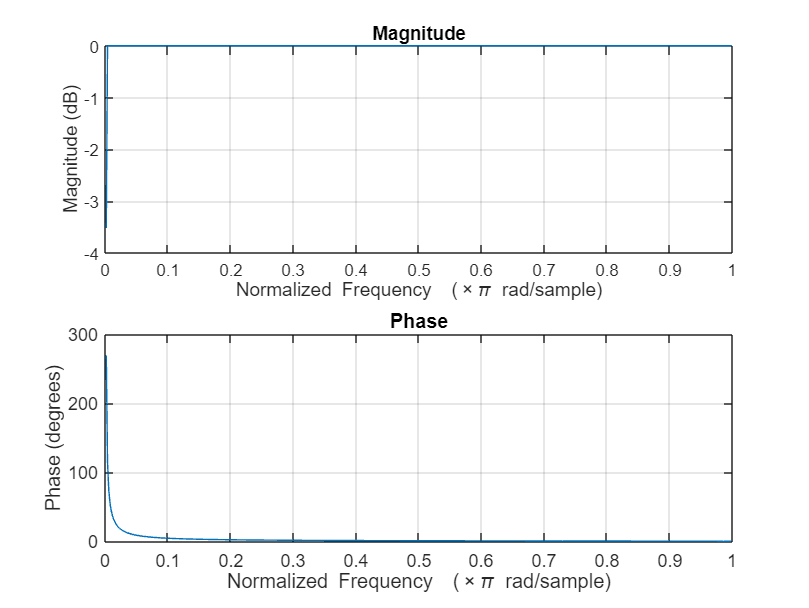

%% High Pass Filter

% Order
highpass_order = 6;

% Cutoff frequencies (Hz)
highpass_freq = 0.5;

% Calculate normalized cutoff frequencies
highpass_Wn = highpass_freq / (fs/2);

% Design lowpass Butterworth filter
[w, z] = butter(highpass_order, highpass_Wn, 'High');

freqz(w, z)


eeg_lowhighpass = filtfilt(w, z, eeg_lowpass);


### 4. Artifact Subspace Reconstruction (ASR)

- **Export EEG data (eeg_bandpass) to EEGLAB**

eeglab;

eeg_lowhighpass_eeglab = eeg_lowhighpass';

- **export eeg_lowhighpass to EEGLAB**

% Import low&high pass eeg data to eeglab
EEG = eeg_emptyset(); % Create an empty EEG structure
EEG.data = eeg_lowhighpass_eeglab; % Your 2D array [channels x time points]
EEG.nbchan = size(EEG.data, 1); % Number of channels
EEG.pnts = size(EEG.data, 2); % Number of time points
EEG.srate = 512; % Sampling rate in Hz, replace with your actual sampling rate
EEG.times = (0:EEG.pnts-1) / EEG.srate; % Time vector (in seconds)
EEG.trials = 1; % Number of epochs (set to 1 for continuous data)
EEG.xmin = EEG.times(1); % Start time
EEG.xmax = EEG.times(end); % End time

% Optionally, set channel information if available
% EEG.chanlocs = ...

% Update EEGLAB with the new dataset
[ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG);
EEG = eeg_checkset(EEG);

- **import eeg_lowhighpass_asr to matlab workspace**

eeg_lowhighpass_asr = EEG.data; % This will be a matrix of size [channels x samples]
eeg_lowhighpass_asr = eeg_lowhighpass_asr';

# EEG Feature Extraction

# **1) Band Power**

## [[ Frequency Domain Feature Extraction ]]

- method for PSD Estimate: *Welch's method*

- each subject: 2 data types (bandpass/ASR) * 12 channels * 5 features

- 5 features: 1) Relative Alpha Power, 2) Relative Theta Power, 3) Relative Theta Power, 4) RBR, 5) Relative Delta Power

### 📌 Define Frequency Bands

FreqTotal = [0.5 40];
FreqDelta = [0.5 4];
FreqTheta = [4 8];
FreqAlpha = [8 12];
FreqBeta = [12 30];
FreqGamma = [30 40];

### 📌 Calculate Frequency Domain Power for all *Channels* and all *Epochs*

% Choose Data Type (bandpass or ASR)
data_type = input('bandpass (0) or ASR (1) or lowhighpass (2) or lowhighpass_ASR (3): ');
if data_type == 1
    eegtype = 'ASR';
    eegselected = eeg_bandpass_asr;
    channelList = {EEG.chanlocs(:).labels};
    folder = sprintf('C:/Users/Natchira/Documents/M.Eng Thesis/MATLAB Drive/All data/Subject%d/BandPowerpxx_ASR', subject);
elseif data_type == 2
    eegtype = 'lowhighpass';
    eegselected = eeg_lowhighpass;
    channelList = channelName;
elseif data_type == 3
    eegtype = 'lowhighpass+ASR';
    eegselected = eeg_lowhighpass_asr;
    channelList = {EEG.chanlocs(:).labels};
else
    eegtype = 'bandpass';
    eegselected = eeg_bandpass;
    channelList = channelName;
    folder = sprintf('C:/Users/Natchira/Documents/M.Eng Thesis/MATLAB Drive/All data/Subject%d/BandPowerpxx_bandpass', subject);
    structName = 'FreqFeatures_Epoch_pxx_bandpass';
end

% % Create the folder if it doesn't exist
% if ~exist(folder, 'dir')
%     mkdir(folder); 
% end

% Set Epoch Length and Overlapping
epochLength = 60; % length of each epoch in seconds
overlap = 0.5*epochLength; % overlap in seconds
fs = dataStruct.fs; % Sampling frequency
numEpochs = floor((size(eegselected, 1) / fs - epochLength) / (epochLength - overlap)) + 1;

% Create Struct to contain features of all epochs from all channels
FreqFeatures_Epoch_pxx = repmat(struct('Epoch', [], 'TotalPower', [], 'AlphaPower', [], ...
    'AlphaRelative', [], 'ThetaPower', [], 'ThetaRelative', [], 'BetaPower1', [], ...
    'BetaPower2', [], 'RBR', [], 'BetaPower', [], 'BetaRelative', [], 'DeltaPower', [], ...
    'DeltaRelative', [], 'AlphaBetaRatio', [], 'TA_BRatio', []), numEpochs, 1);

% Loop Through Each Channel and Each Epoch to Extract Features
% Loop Through Each Channel
for channelIdx = 1:length(channelList)
    channel = channelList{channelIdx};
    
    % Loop Through Each Epoch
    for epoch = 1:numEpochs
        startTime = (epoch-1) * (epochLength - overlap); % Start time in seconds for the current epoch
        endTime = startTime + epochLength; % End time in seconds for the current epoch

        % Calculate the corresponding indices
        startIndex = round(startTime * fs) + 1;
        endIndex = round(endTime * fs);

        % Make sure endIndex does not exceed data length
        endIndex = min(endIndex, size(eegselected, 1));
    
        % Extract the relevant portion of the data for the current channel
        dataSegment = eegselected(startIndex:endIndex, channelIdx);

        % Calculate PSD Estimate
        [pxx, f] = pwelch(dataSegment, [], [], [], fs); % Welch's power PSD estimate
        % [pxx, f] = periodogram(dataSegment, [], [], fs); % Periodogram PSD estimate


    % calculate bandpower of each dataSegment
        PowerTotal = bandpower(pxx, f, FreqTotal, 'psd');
        PowerAlpha = bandpower(pxx, f, FreqAlpha, 'psd');
        PowerAlphaRelative = PowerAlpha / PowerTotal;
        PowerTheta = bandpower(pxx, f, FreqTheta, 'psd');
        PowerThetaRelative = PowerTheta / PowerTotal;
        PowerBeta1 = bandpower(pxx, f, [30 47], 'psd');
        PowerBeta2 = bandpower(pxx, f, [11 20], 'psd');
        RBR = PowerBeta1/PowerBeta2;
        PowerBeta = bandpower(pxx, f, FreqBeta, 'psd');
        PowerBetaRelative = PowerBeta / PowerTotal;
        PowerDelta = bandpower(pxx, f, FreqDelta, 'psd');
        PowerDeltaRelative = PowerDelta / PowerTotal;
        PowerAlphaBeta = PowerAlpha/PowerBeta;
        PowerTA_BRatio = (PowerTheta + PowerAlpha)/PowerBeta;

    % Store in struct
        FreqFeatures_Epoch_pxx(epoch, channelIdx).Epoch = epoch;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).TotalPower = PowerTotal;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).AlphaPower = PowerAlpha;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).AlphaRelative = PowerAlphaRelative;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).ThetaPower = PowerTheta;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).ThetaRelative = PowerThetaRelative;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).BetaPower1 = PowerBeta1;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).BetaPower2 = PowerBeta2;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).RBR = RBR;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).BetaPower = PowerBeta;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).BetaRelative = PowerBetaRelative;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).DeltaPower = PowerDelta;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).DeltaRelative = PowerDeltaRelative;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).AlphaBetaRatio = PowerAlphaBeta;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).TA_BRatio = PowerTA_BRatio;

    end

    % Create Plot for relative power features of 1 channel
    % all features in 1 plot
    figure;
    subplot(2,1,1);
    TimeIndex = [FreqFeatures_Epoch_pxx(:, channelIdx).Epoch]*70/numEpochs;
    plot(TimeIndex, [FreqFeatures_Epoch_pxx(:, channelIdx).AlphaRelative], '-o', 'MarkerSize', 2, 'DisplayName', 'Relative Alpha Power');
    hold on
    plot(TimeIndex, [FreqFeatures_Epoch_pxx(:, channelIdx).ThetaRelative], '-ro', 'MarkerSize', 2, 'MarkerEdgeColor', 'r', 'DisplayName', 'Relative Theta Power');
    hold on
    plot(TimeIndex, [FreqFeatures_Epoch_pxx(:, channelIdx).BetaRelative], '-o', 'MarkerSize', 2, 'MarkerEdgeColor', 'auto', 'DisplayName', 'Relative Beta Power');
    hold on
    % plot(TimeIndex, [FreqFeatures_Epoch_pxx(:, channelIdx).RBR], '-go', 'MarkerSize', 2, 'MarkerEdgeColor', 'auto', 'DisplayName', 'RBR');
    % hold on
    plot(TimeIndex, [FreqFeatures_Epoch_pxx(:, channelIdx).DeltaRelative], '-o', 'MarkerSize', 2, 'MarkerEdgeColor', 'auto', 'DisplayName', 'Relative Delta Power');
    
    legend;
    xlabel('Time (minutes)');
    ylabel('Relative Frequency Power');
    title(sprintf('[Subject %d] Channel %s (%s): Frequency Domain Features (welch)', subject, channel, eegtype));

    subplot(2,1,2);
    plot(TimeIndex, [FreqFeatures_Epoch_pxx(:, channelIdx).AlphaBetaRatio], '-o', 'MarkerSize', 2, 'MarkerEdgeColor', 'auto', 'DisplayName', 'Alpha/Beta Ratio');
    hold on
    plot(TimeIndex, [FreqFeatures_Epoch_pxx(:, channelIdx).TA_BRatio], '-o', 'MarkerSize', 2, 'MarkerEdgeColor', 'auto', 'DisplayName', '(Theta+Alpha)/Beta Ratio');

    legend;
    xlabel('Time (minutes)');
    ylabel('Ratio');

    % % Save the figure
    % outputFilename = sprintf('Subject%d_%s(%s)_RelativeFrequencyPower(welch).png', subject, channel, eegtype);
    % saveas(gcf, fullfile(folder, outputFilename));
    % close(gcf); % Close the figure after saving to free up system resources
end

if data_type == 1
    FreqFeatures_Epoch_pxx_ASR = FreqFeatures_Epoch_pxx
elseif data_type == 2
    FreqFeatures_Epoch_pxx_lowhighpass = FreqFeatures_Epoch_pxx
elseif data_type == 3
    FreqFeatures_Epoch_pxx_lowhighpassASR = FreqFeatures_Epoch_pxx
else 
    FreqFeatures_Epoch_pxx_bandpass = FreqFeatures_Epoch_pxx
end

% Now, FreqFeatures contains the feature data for each epoch